# *E.coli *(iJO1366) "Valine, Leucine, and Isoleucine Metabolism" 

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Valine, Leucine, and Isoleucine Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1.  Valine, Leucine and Isoleucine Metabolism**

The purpose of this tutorial is to identify and review the structure and capabilities of the "Valine, Leucine, and Isoleucine Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-Valine, L-Leucine and L-Isoleucine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in an oxidative range from anaerobic to aerobic conditions.

## **2. "**Valine, Leucine, and Isoleucine Metabolism**" Subsystem**

The reactions associated with the "Valine, Leucine, and Isoleucine Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
ValineLeucineIsoleucineSubSystems = {'Valine, Leucine, and Isoleucine Metabolism'};
ValineLeucineIsoleucineReactions = model.rxns(ismember(model.subSystems,ValineLeucineIsoleucineSubSystems));
[tmp,ValineLeucineIsoleucine_rxnID] = ismember(ValineLeucineIsoleucineReactions,model.rxns);
reactionNames = model.rxnNames(ValineLeucineIsoleucine_rxnID);
reactionFormulas = printRxnFormula(model,ValineLeucineIsoleucineReactions,0);
% T = table(reactionNames,reactionFormulas,'RowNames',ValineLeucineIsoleucineReactions)
fid = 1;
fprintf(fid,'%-12s %-70s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction     Reaction Name                                                          Reaction Formula                                  


[nrows,ncols] = size(ValineLeucineIsoleucineReactions);
for row = 1:nrows
    fprintf(fid,'%-12s %-70s %-50s\r\n',ValineLeucineIsoleucineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ACHBS        2-aceto-2-hydroxybutanoate synthase                                    2obut_c + h_c + pyr_c  -> 2ahbut_c + co2_c        
ACLS         Acetolactate synthase                                                  h_c + 2 pyr_c  -> alac__S_c + co2_c               
DHAD1        Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylbutanoate)           23dhmb_c  -> 3mob_c + h2o_c                       
DHAD2        Dihydroxy-acid dehydratase (2,3-dihydroxy-3-methylpentanoate)          23dhmp_c  -> 3mop_c + h2o_c                       
ILETA        Isoleucine transaminase                                                akg_c + ile__L_c  <=> 3mop_c + glu__L_c           
IPMD         3-isopropylmalate dehydrogenase                                        3c2hmp_c + nad_c  -> 3c4mop_c + h_c + nadh_c      
IPPMIa       3-isopropylmalate dehydratase                                          3c2hmp_c  <=> 2ippm_c + h2o_c                     
IPPMIb       2-isopropylmalate hydratase               

**Table 1. **Reaction names and formulas for the  "Valine, Leucine, and Isoleucine Metabolism" subsystem.

The connectivity between these reactions can be visualized through an Escher [3] map of this  "Valine, Leucine, and Isoleucine Metabolism" subsystem as shown below (Valine_Leucine_Isoleucine_Metabolism_Subsystem.json).

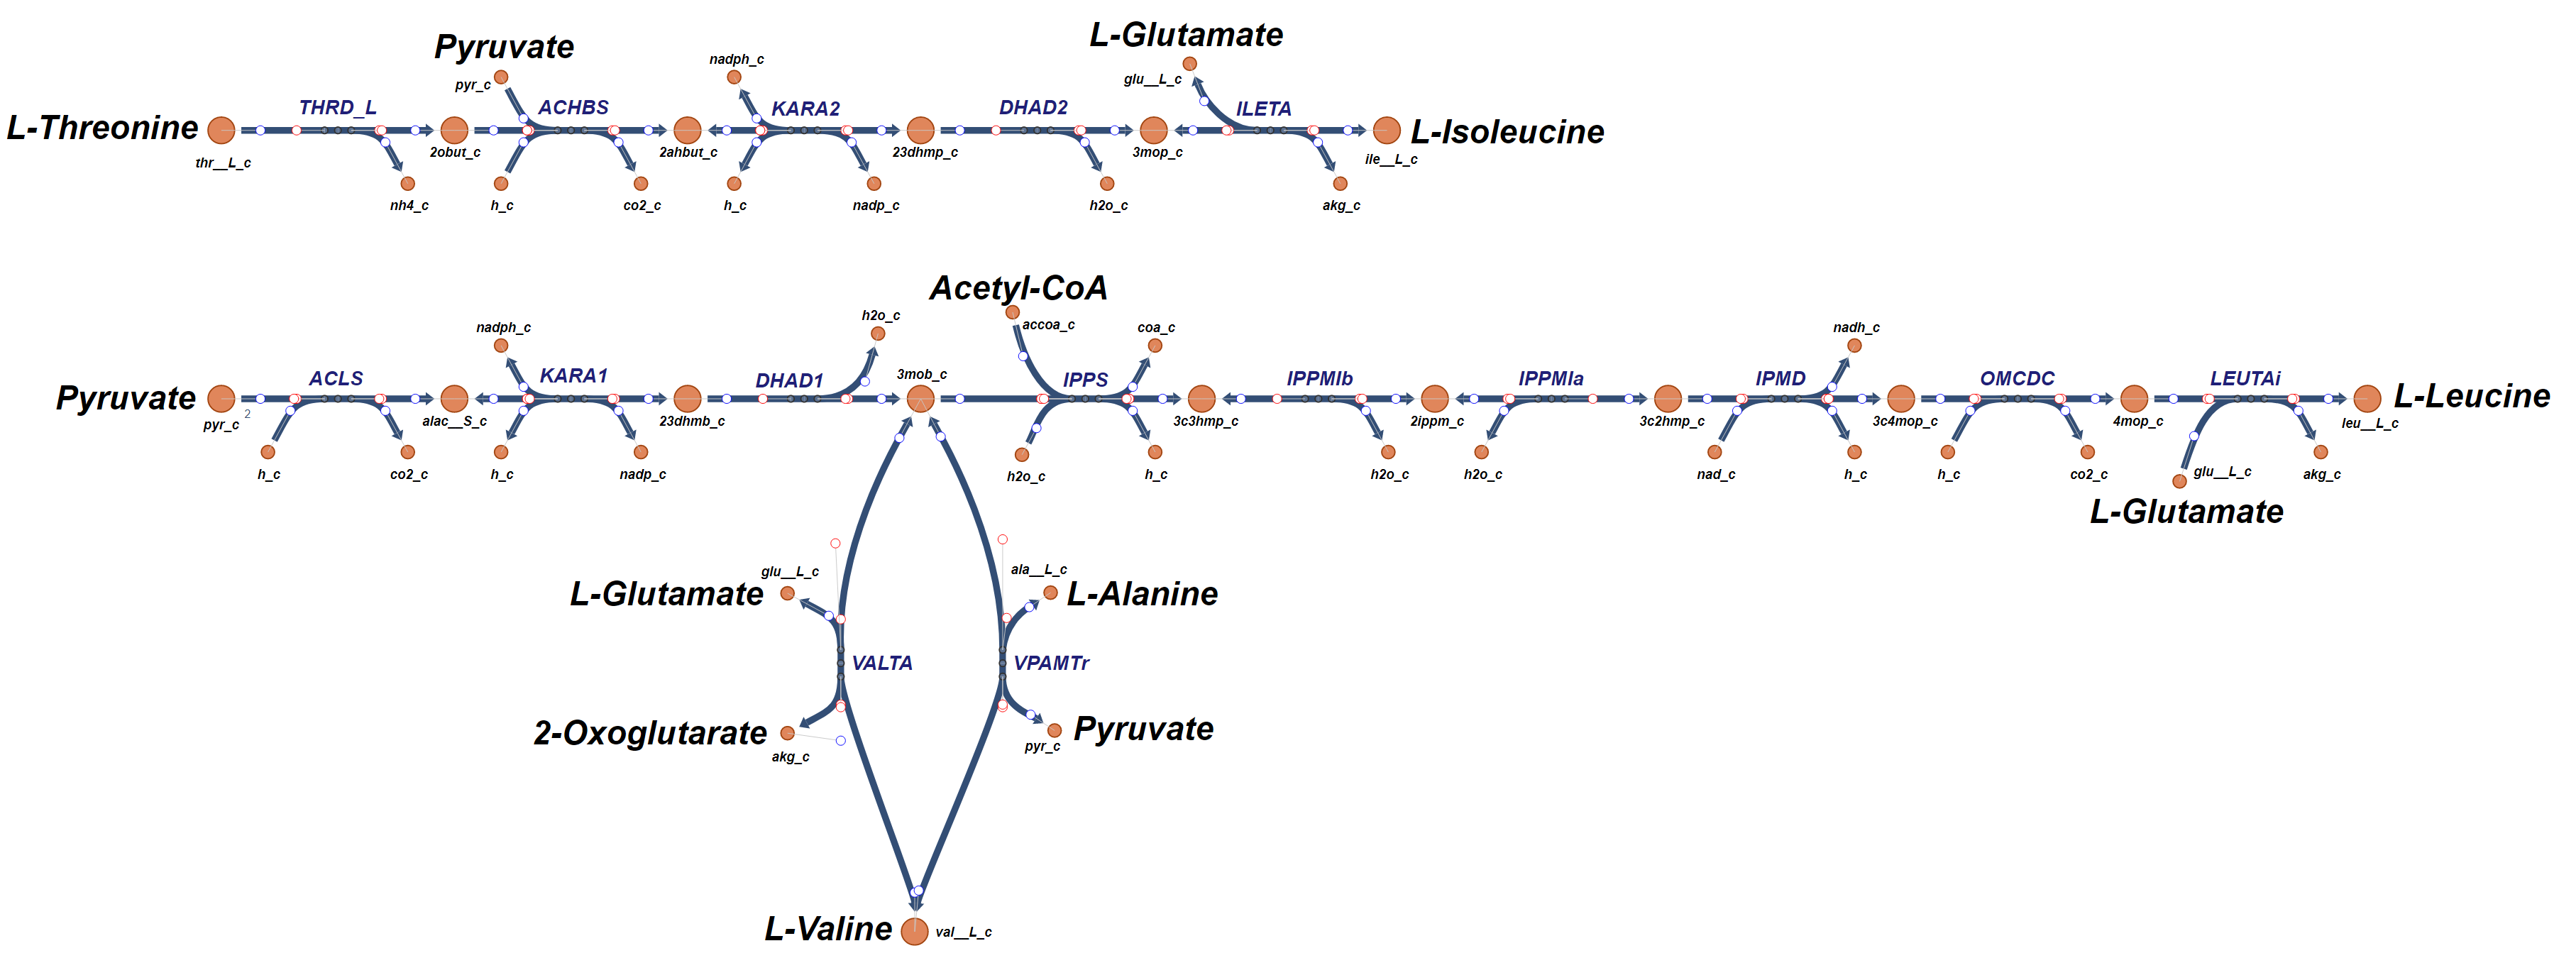

**Figure 1.** The reactions and pathways associated with the "Valine, Leucine, and Isoleucine Metabolism" subsystem.

The  "Valine, Leucine, and Isoleucine Metabolism" xxx

Now let's begin exploring the biosynthesis pathways for L-Valine, L-Leucine, and L-arginine.

## **3. L-Valine Biosynthesis**

L-Valine is one of the simplest α-amino acids The α-carbon atom of Valine is bound to a methyl group (-CH3) resulting in Valine's classification as an aliphatic amino acid. The right-handed form of Valine, D-Valine is found in bacterial cell walls and in some peptide antibiotics.

## 3.1. L-Valine Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsystem there are only three reactions that produce L-Valine;  'ALATA_L', 'ALAR', and 'DAAD'. The first of these reactions ('ALATA_L) provides the single reaction pathway from the L-Valine precursor pyruvate. The second reaction ( 'ALAR') is a bidirectional reaction that converts D-Valine ('ala__D_c') to L-Valine. The third of these reaction converts D-Valine to pyruvate. To explore the posssibility of other L-Valine production pathways we can use the sufNet function we can identify all the reactions that can directly produce L-Valine.

surfNet(model, 'ala__L_c')


Met #255  ala__L_c, L-Alanine, C3H7NO2
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

By looking at the bottome of this print-out we can see that there are seven reactions, when operating in the forward direction, can produce L-Valine; including 'ALAabcpp', 'ALAt2pp_copy1', 'ALAt2pp_copy2', 'ALAt4pp', 'CYSSADS', 'ICYSDS', 'LALGP', 'SCYSDS'. Notice that all these reactions, except 'ALAt2pp_copy2', are irreversible which implies that flux can only flow in the forward direction. By looking at the "Consuming reactions" listed about the "Producing reactions" you will notice that there are three reversible reactions that include 'ALAR', 'ALATA_L', and 'VPAMTr'. When these reactions are operating in the reverse direcdtion they will also be L-Valine producers.

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Valine.

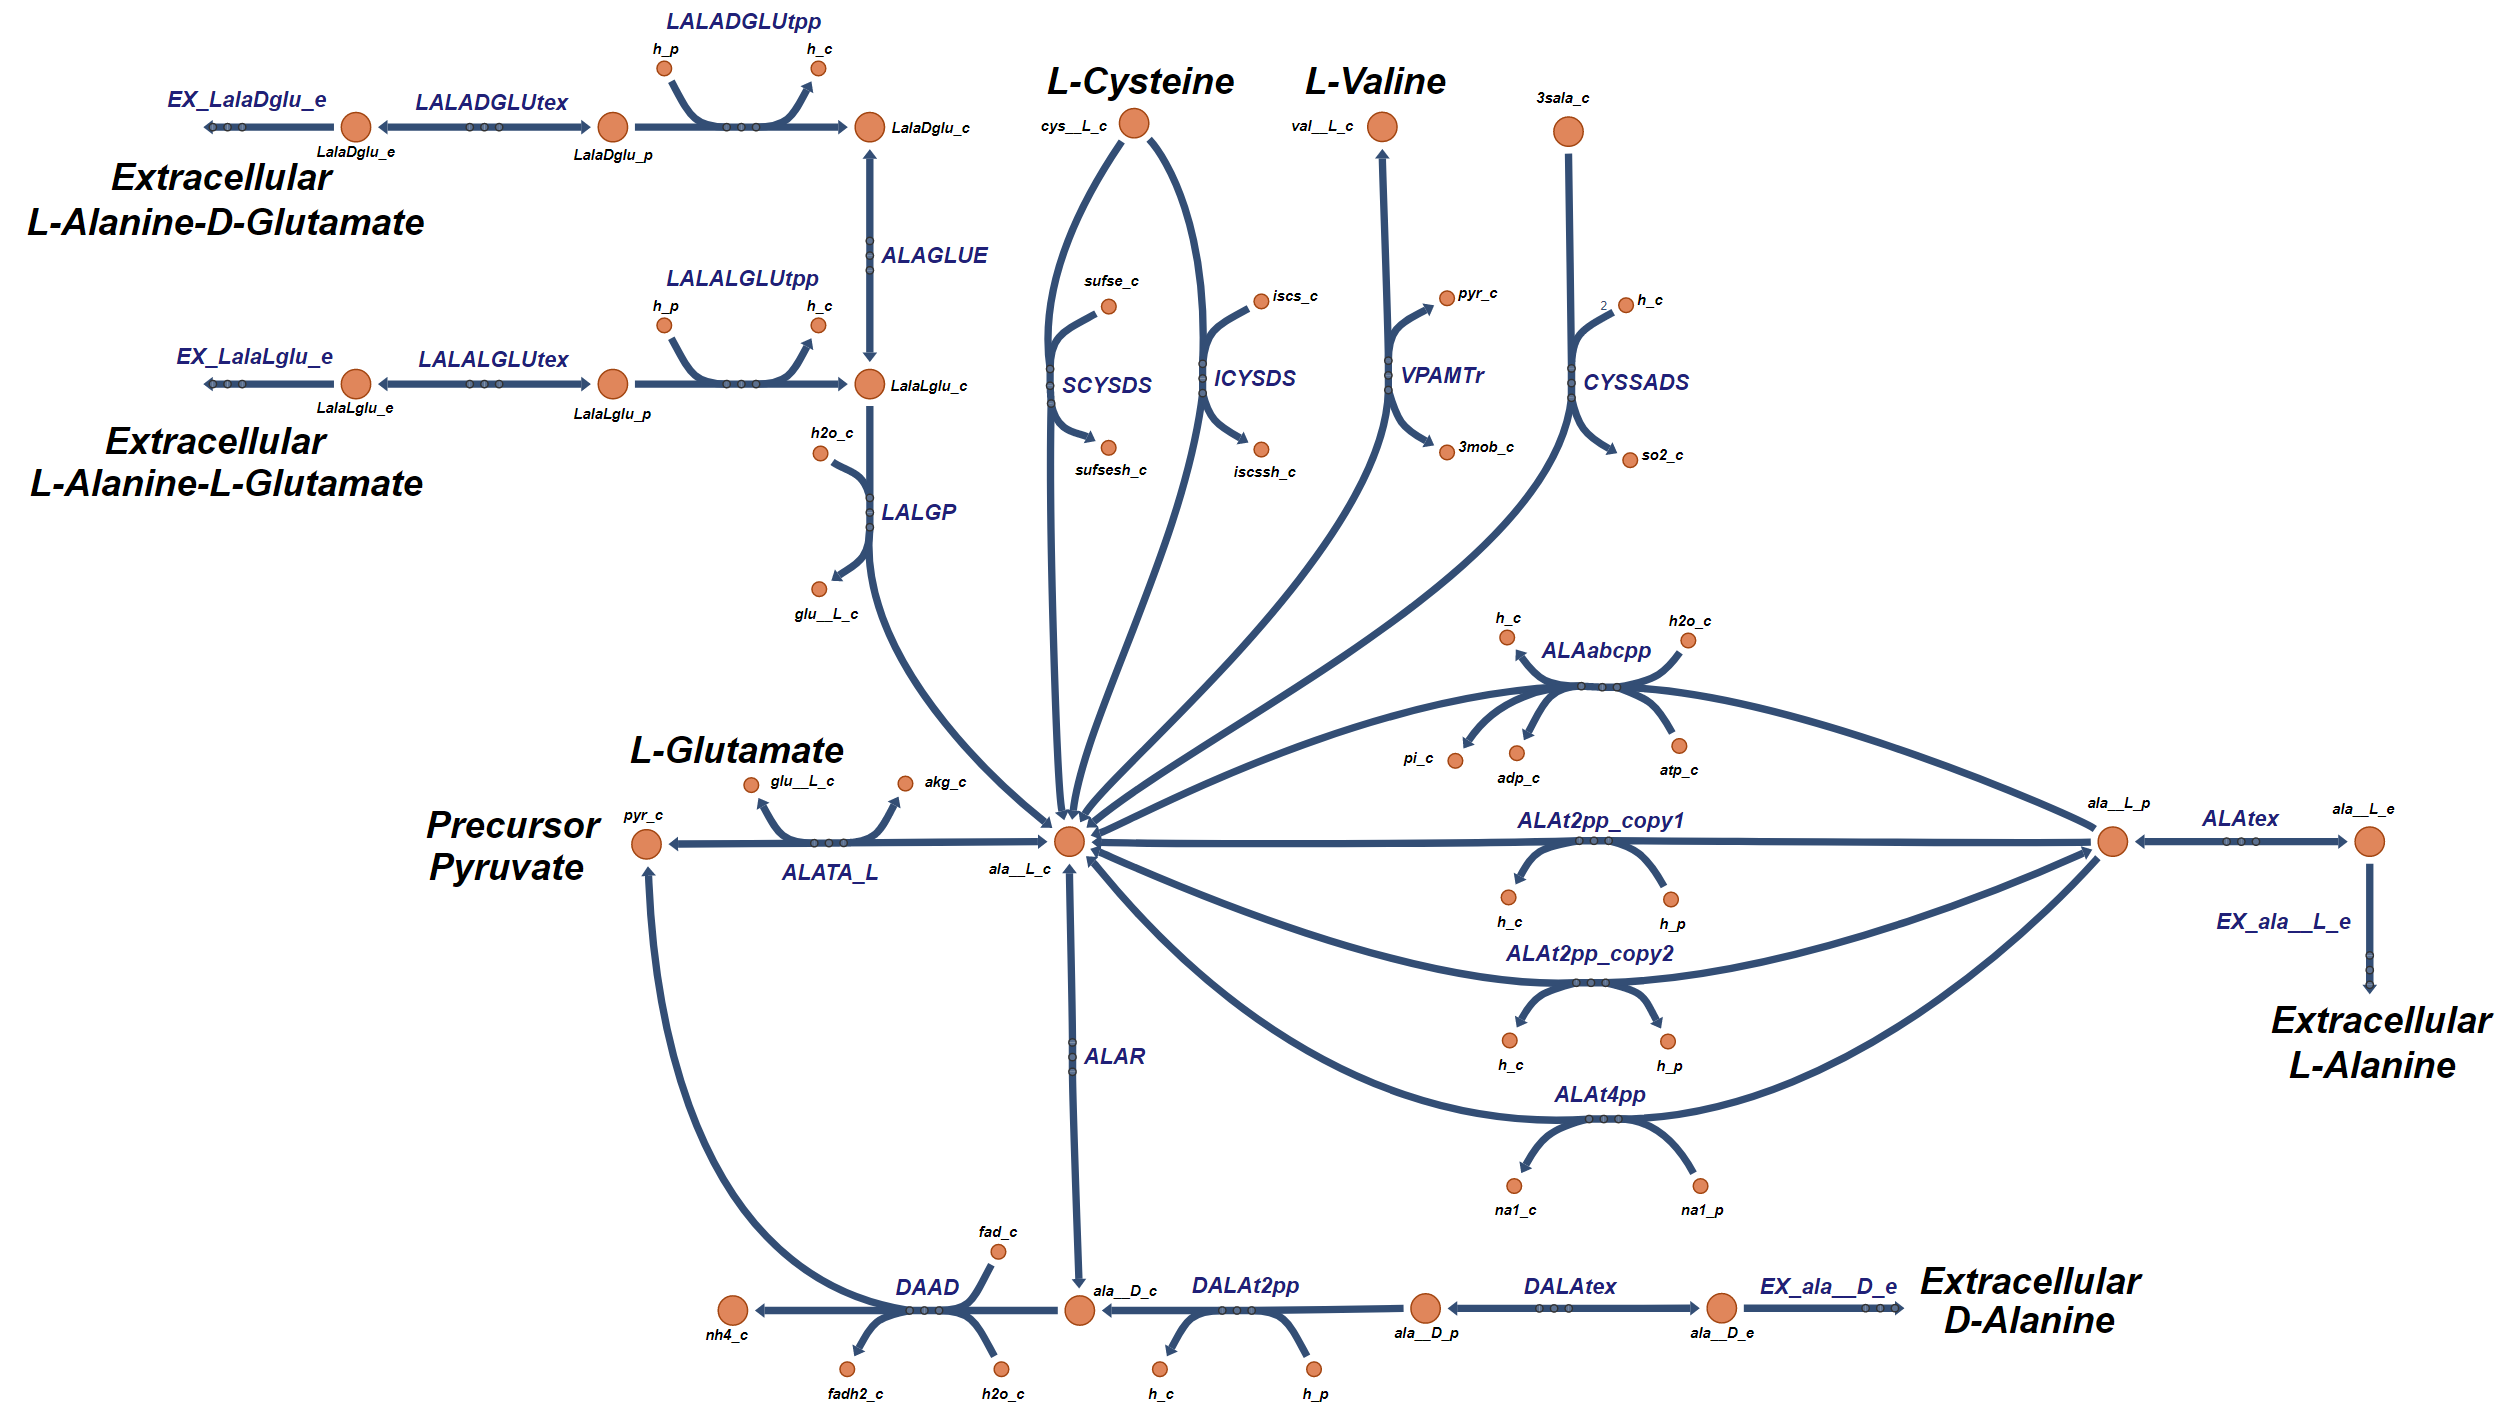

**Figure 3.** Biosynthesis pathways for the production of L-Valine.

The Escher tool allows easy access to the reactions that precede these final L-Valine producing reactions. Using this tool we can notice several different paths that can lead to L-Valine production. Let's start by looking at the pathway on the upper left of this figure. This pathway provides the conversion from extracellular L-Valine-D-Glutamate ('LalaDglu_e') to L-Valine through 5 reactions ('EX_LalaDglu_e', 'LALADGLUtex', 'LALADGLUtpp', 'ALAGLUE', and 'LALGP'). A simlar pathway, located below it, provides the conversion from extracellular L-Valine-L-Glutamate ('LalaLglu_e') to L-Valine through 4 reactions ('EX_LalaLglu_e', 'LALALGLUtex', 'LALALGLUtpp', and 'LALGP'). On the top of this figure there are 4 other pathways the can lead to the production of L-Valine. The first two begine with L-cysteine ('cys__L_c') as the initial substrate and use either 'SCYSDS or ICYSDS' to create the L-Valine product.There is another pathways that begins with L-valine ('val__L_c') and uses VPAMTr to create the L-Valine. In the model, there is another pathway that uses the reaction 'CYSSADS', unfortunately this is a dead-end reaction since there is no way for the intiial substrate 3-Sulfino-L-Valine ('3sala_c') to be created within the model. To the left of the figure is the primary pathway that starts with the precursor pyrvate ('pyr_c') and uses the reaction 'ALATA_L'. Another path that can begin with pyruvate includes 'DAAD' and 'ALAR'. On the right bottom is a pathway that begins with extracellular D-Valine ('ala__D_e') and passes through four reactions ('EX_ala__D_e',  'DALAtex', 'DALAt2pp', and 'ALAR') in the process of conversion to L_Valine. Finally, there are four transporters ('ALAabcpp', 'ALAt2pp_copy1', 'ALAt2pp_copy2', and 'ALAt4pp') that can transport diffused extracellular L-Valine ('ala__L_e') into the cytoplasm.

## 3.2 L-Valine Aerobic Operation

The fluxes for these L-Valine producing reactions can be extracted from the iJO1366 model as follows.

ValineReactions = transpose({'ALATA_L','DAAD','ALAR','ALAabcpp','ALAt2pp_copy1','ALAt2pp_copy2','ALAt4pp',...
    'EX_ala__D_e','DALAtex','DALAt2pp','EX_LalaDglu_e','LALADGLUtex','LALADGLUtpp','ALAGLUE',...
    'EX_LalaLglu_e','LALALGLUtex','LALALGLUtpp','LALGP','SCYSDS','ICYSDS','VPAMTr','CYSSADS'});
[tmp,Valine_rxnID] = ismember(ValineReactions,model.rxns);
reactionNames = model.rxnNames(Valine_rxnID);
reactionSubsystem = model.subSystems(Valine_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',ValineReactions)

T = 22×2 table
                                                    reactionNames                                                reactionSubsystem              
                     ___________________________________________________________________________    ____________________________________________

    ALATA_L          'L-alanine transaminase'                                                       'Alanine and Aspartate Metabolism'          
    DAAD             'D-Amino acid dehydrogenase'                                                   'Alanine and Aspartate Metabolism'          
    ALAR             'Alanine racemase'                                                             'Alanine and Aspartate Metabolism'          
    ALAabcpp         'L-alanine transport via ABC system (periplasm)'                               'Transport, Inner Membr

Now let's explore the flux through these L-Valine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(ValineReactions, round(FBAsolution.x(Valine_rxnID),3))

ALATA_L	-0.571	
DAAD	0	
ALAR	0.041	
ALAabcpp	0	
ALAt2pp_copy1	0	
ALAt2pp_copy2	0	
ALAt4pp	0	
EX_ala__D_e	0	
DALAtex	0	
DALAt2pp	0.014	
EX_LalaDglu_e	0	
LALADGLUtex	0	
LALADGLUtpp	0	
ALAGLUE	0	
EX_LalaLglu_e	0	
LALALGLUtex	0	
LALALGLUtpp	0	
LALGP	0	
SCYSDS	0	
ICYSDS	0.002	
VPAMTr	0	
CYSSADS	-0	


This can be seen using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

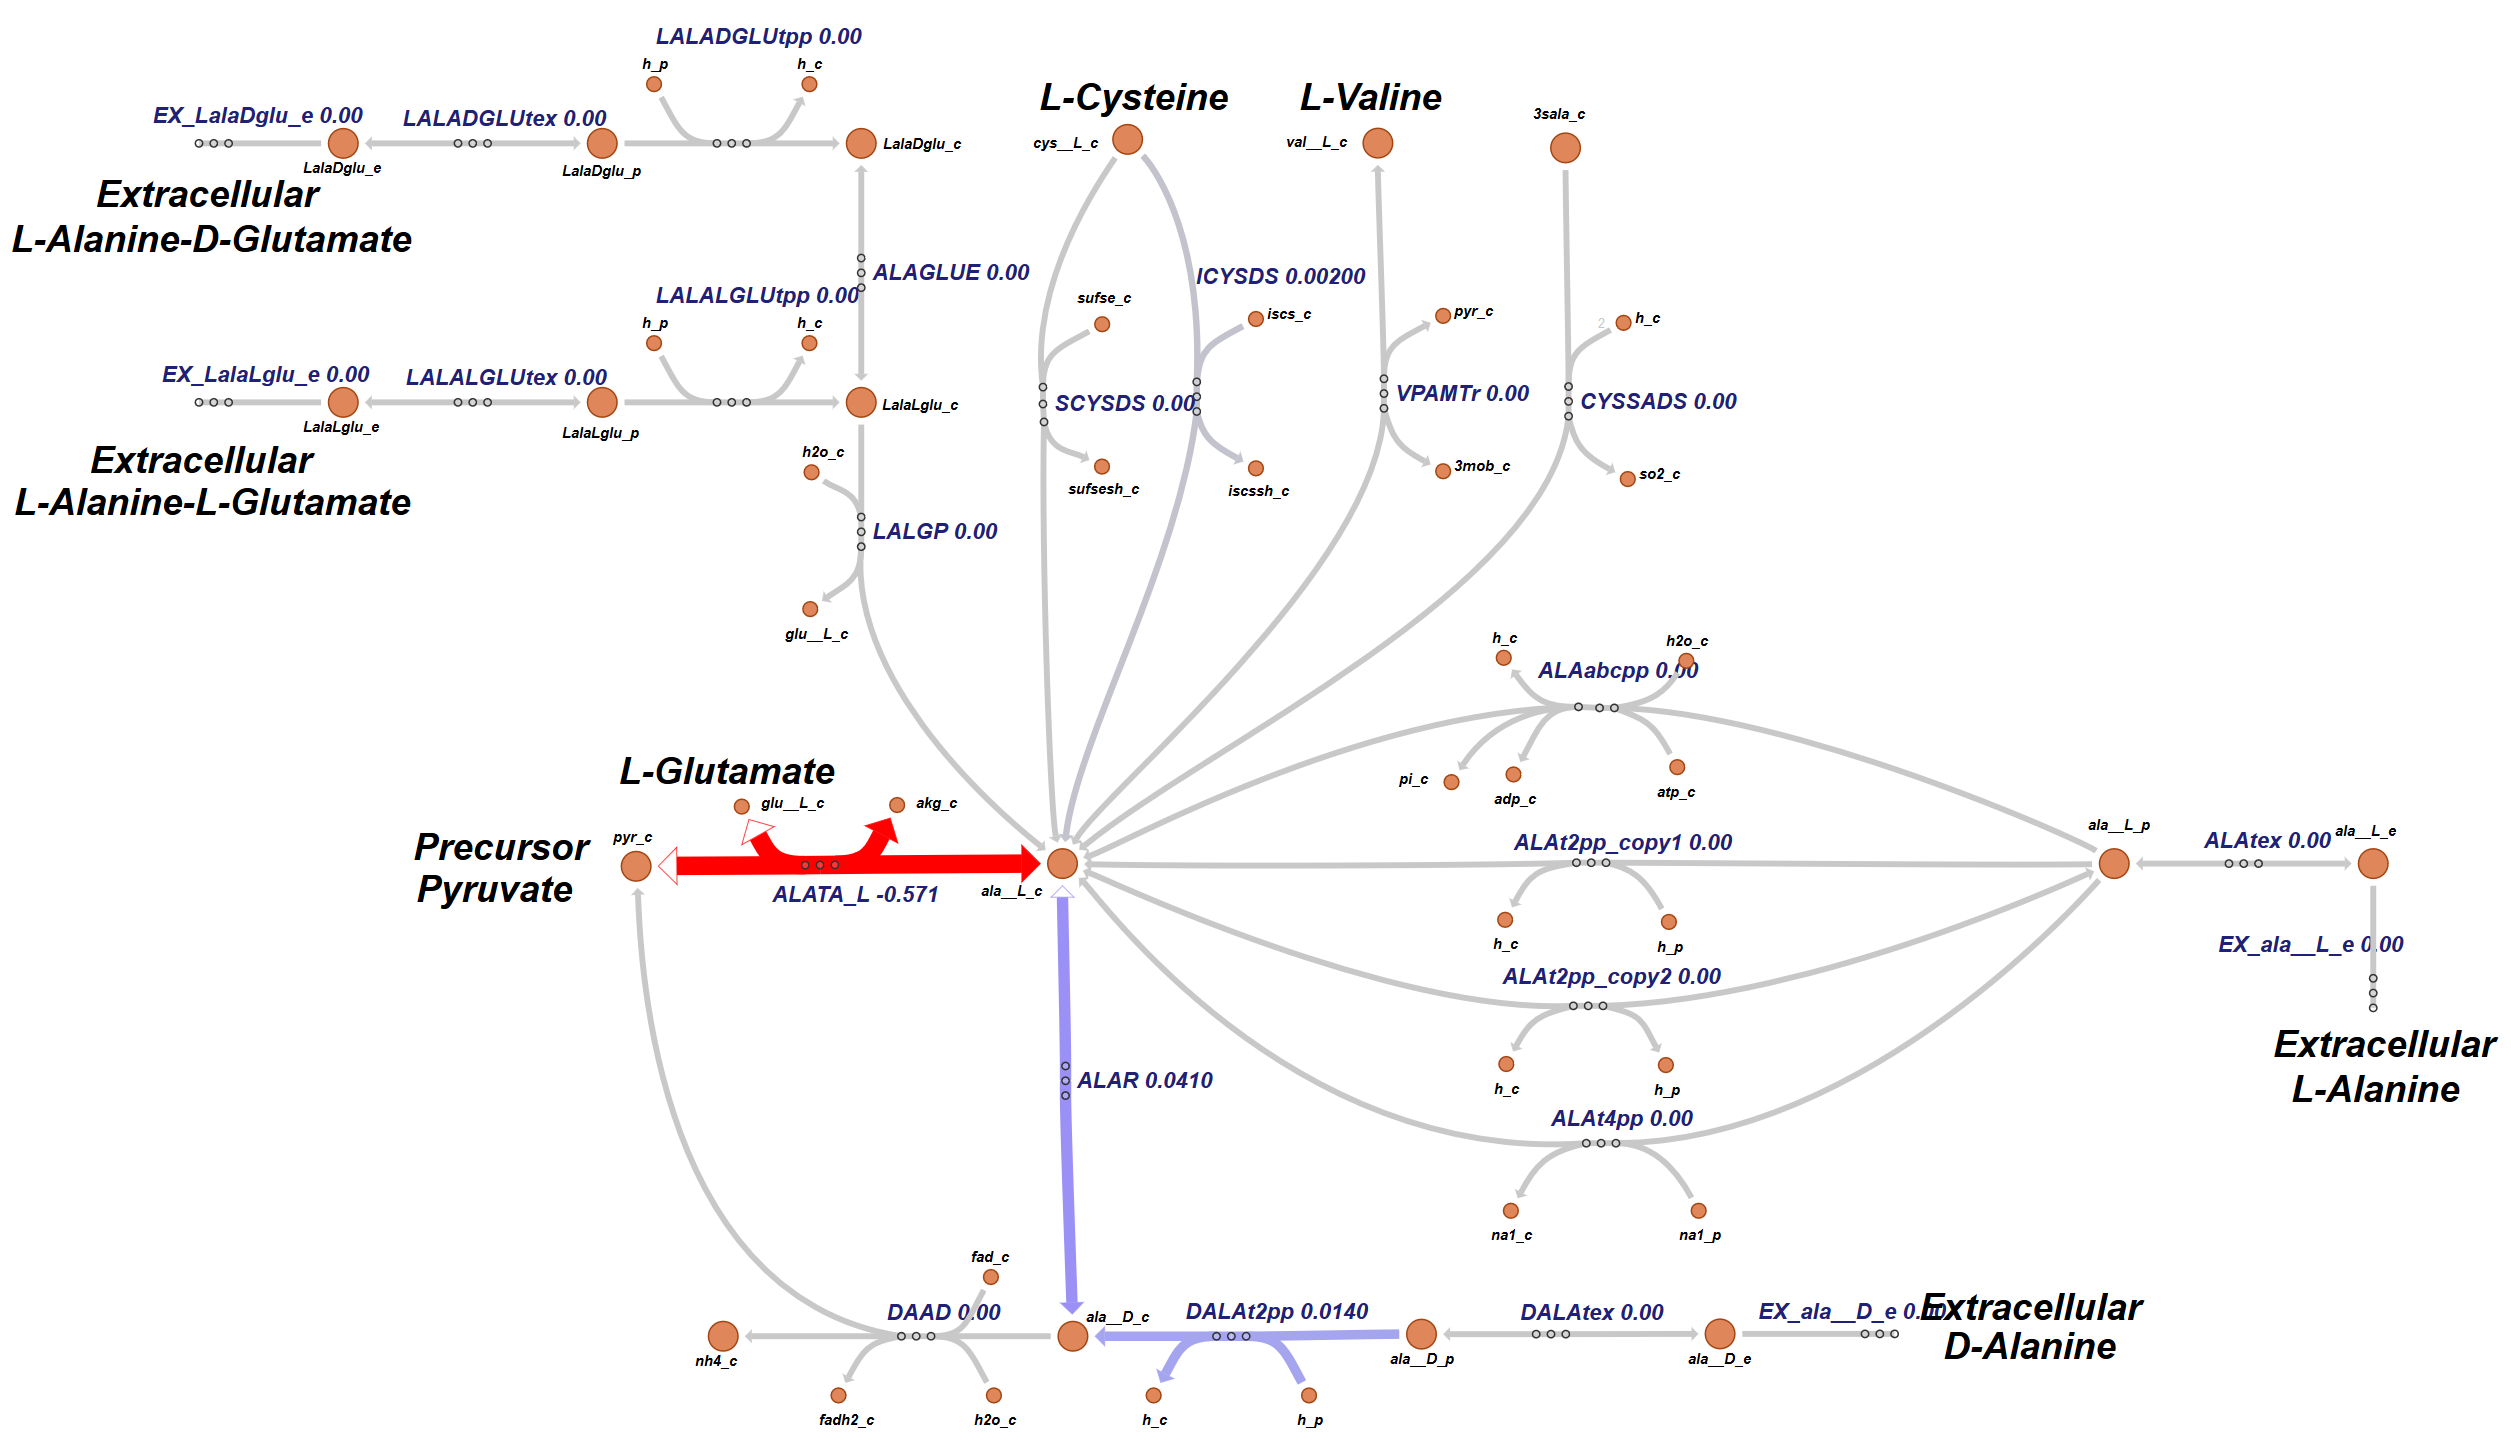

**Figure 4.** L-Valine production under aerobic conditions.

It can be seen that the majority of the L-Valine flux is produced through the primary pathway ('ALATA_L') with a small amount being contributed from the D-Valine pool ('DALAt2rpp' and 'ALAR'), and an even smaller amount from the L-cysteine pool ('ICYSDS'). 

## 3.3 Excess L-Valine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Valine for the desired bioproduct.  What is the maximum amount of excess L-Valine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'ala__L_c');

DM_ala__L_c	ala__L_c 	->	


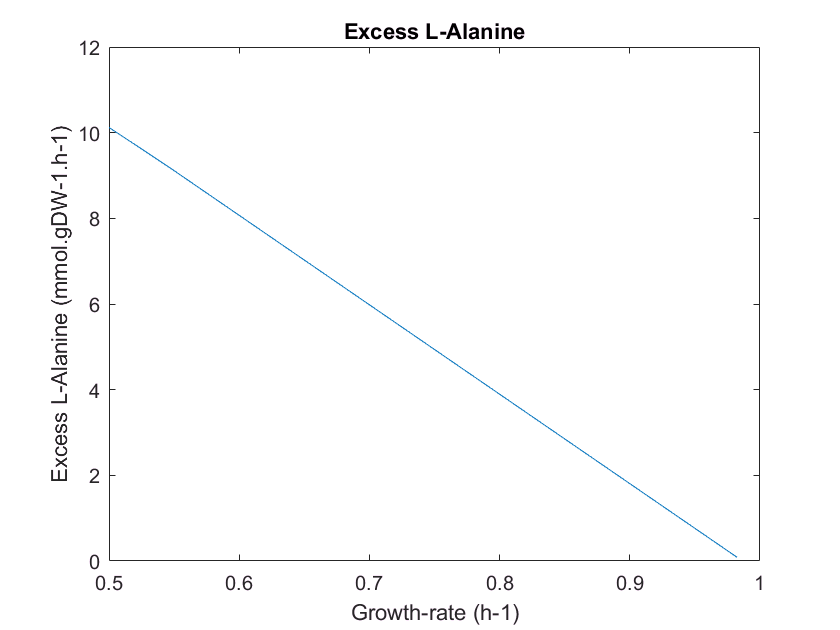

[tmp,Valine_MAX_rxnID] = ismember({'DM_ala__L_c'},model.rxns);
model = changeObjective(model,'DM_ala__L_c'); % Set the objective function
FBAsolution_Valine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessValine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Valine = optimizeCbModel(model,'max'); % Perform FBA
    excessValine(i) = FBAsolution_Valine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessValine)
title('Excess L-Valine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Valine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Valine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Valine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Valine flux can increase from 0.08649 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 10.12 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Valine flux beyond these levels will require using the pathways that allow for the transport of L-Valine from the extracellular media. 

## **4. L-Leucine Biosynthesis**

L-Leucine is xxx

## 4.1.  **L-Leucine** Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsytem in Figure 1 there are only two reactions that can produce cytoplasmic L-Leucine,  'ASNN' and 'ASPTA'. The first reaction is used to convert L-arginine ('asn__L_c' ) to L-Leucine ('asp__L_c'). The second reaction ('ASPTA' ) is a reversible reaction that serves as the primary pathway for the L-asparate precursor oxaloacetate ('oaa_c'). 

To explore the posssibility of other L-Leucine production pathways, we can use the "surfNet" COBRA toolbox function to identify all the reactions that can produce L-Leucine.

surfNet(model, 'asp__L_c')


Met #302  asp__L_c, L-Aspartate, C4H6NO4
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are seven reactions that produce cytoplasmic L-Leucine in the forward direction, they include  'ASNN', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and 'SUCASPtpp'. The rest of the reactions are transporters that can be used to uptake L-Leucine ('asp__L_p')  from the periplasm to the cytoplasmic space ('asp__L_c').  The first of these transporters is an ABC transporter ( 'ASPabcpp') that requires ATP to move to traposport the L-Leucine. The next four reactions ( 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2') require energy from the proton-motive force to transport L-Leucine. The final reaction is an antiporter that moves succinate from the cytoplasm ('succ_c' ) to the periplasm ('succ_p' ) while also move L-Leucine from the periplasm ('asp__L_p') to the cytoplasm ('asp__L_c'). 

Other reactions that could act to produce L-Leucine are the reversible reactions listed under the "Consuming reactions" produced above by surfNet. These reversible reactions include 'ASPK' and 'ASPTA'. The first of these reaction ('ASPK') provides connectivity between the L-Leucine and the L-lysine & L-threonine metabolism. While the second reaction ('ASPTA') serves as the primary pathway for the L-asparate precursor oxaloacetate ('oaa_c').

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Leucine.

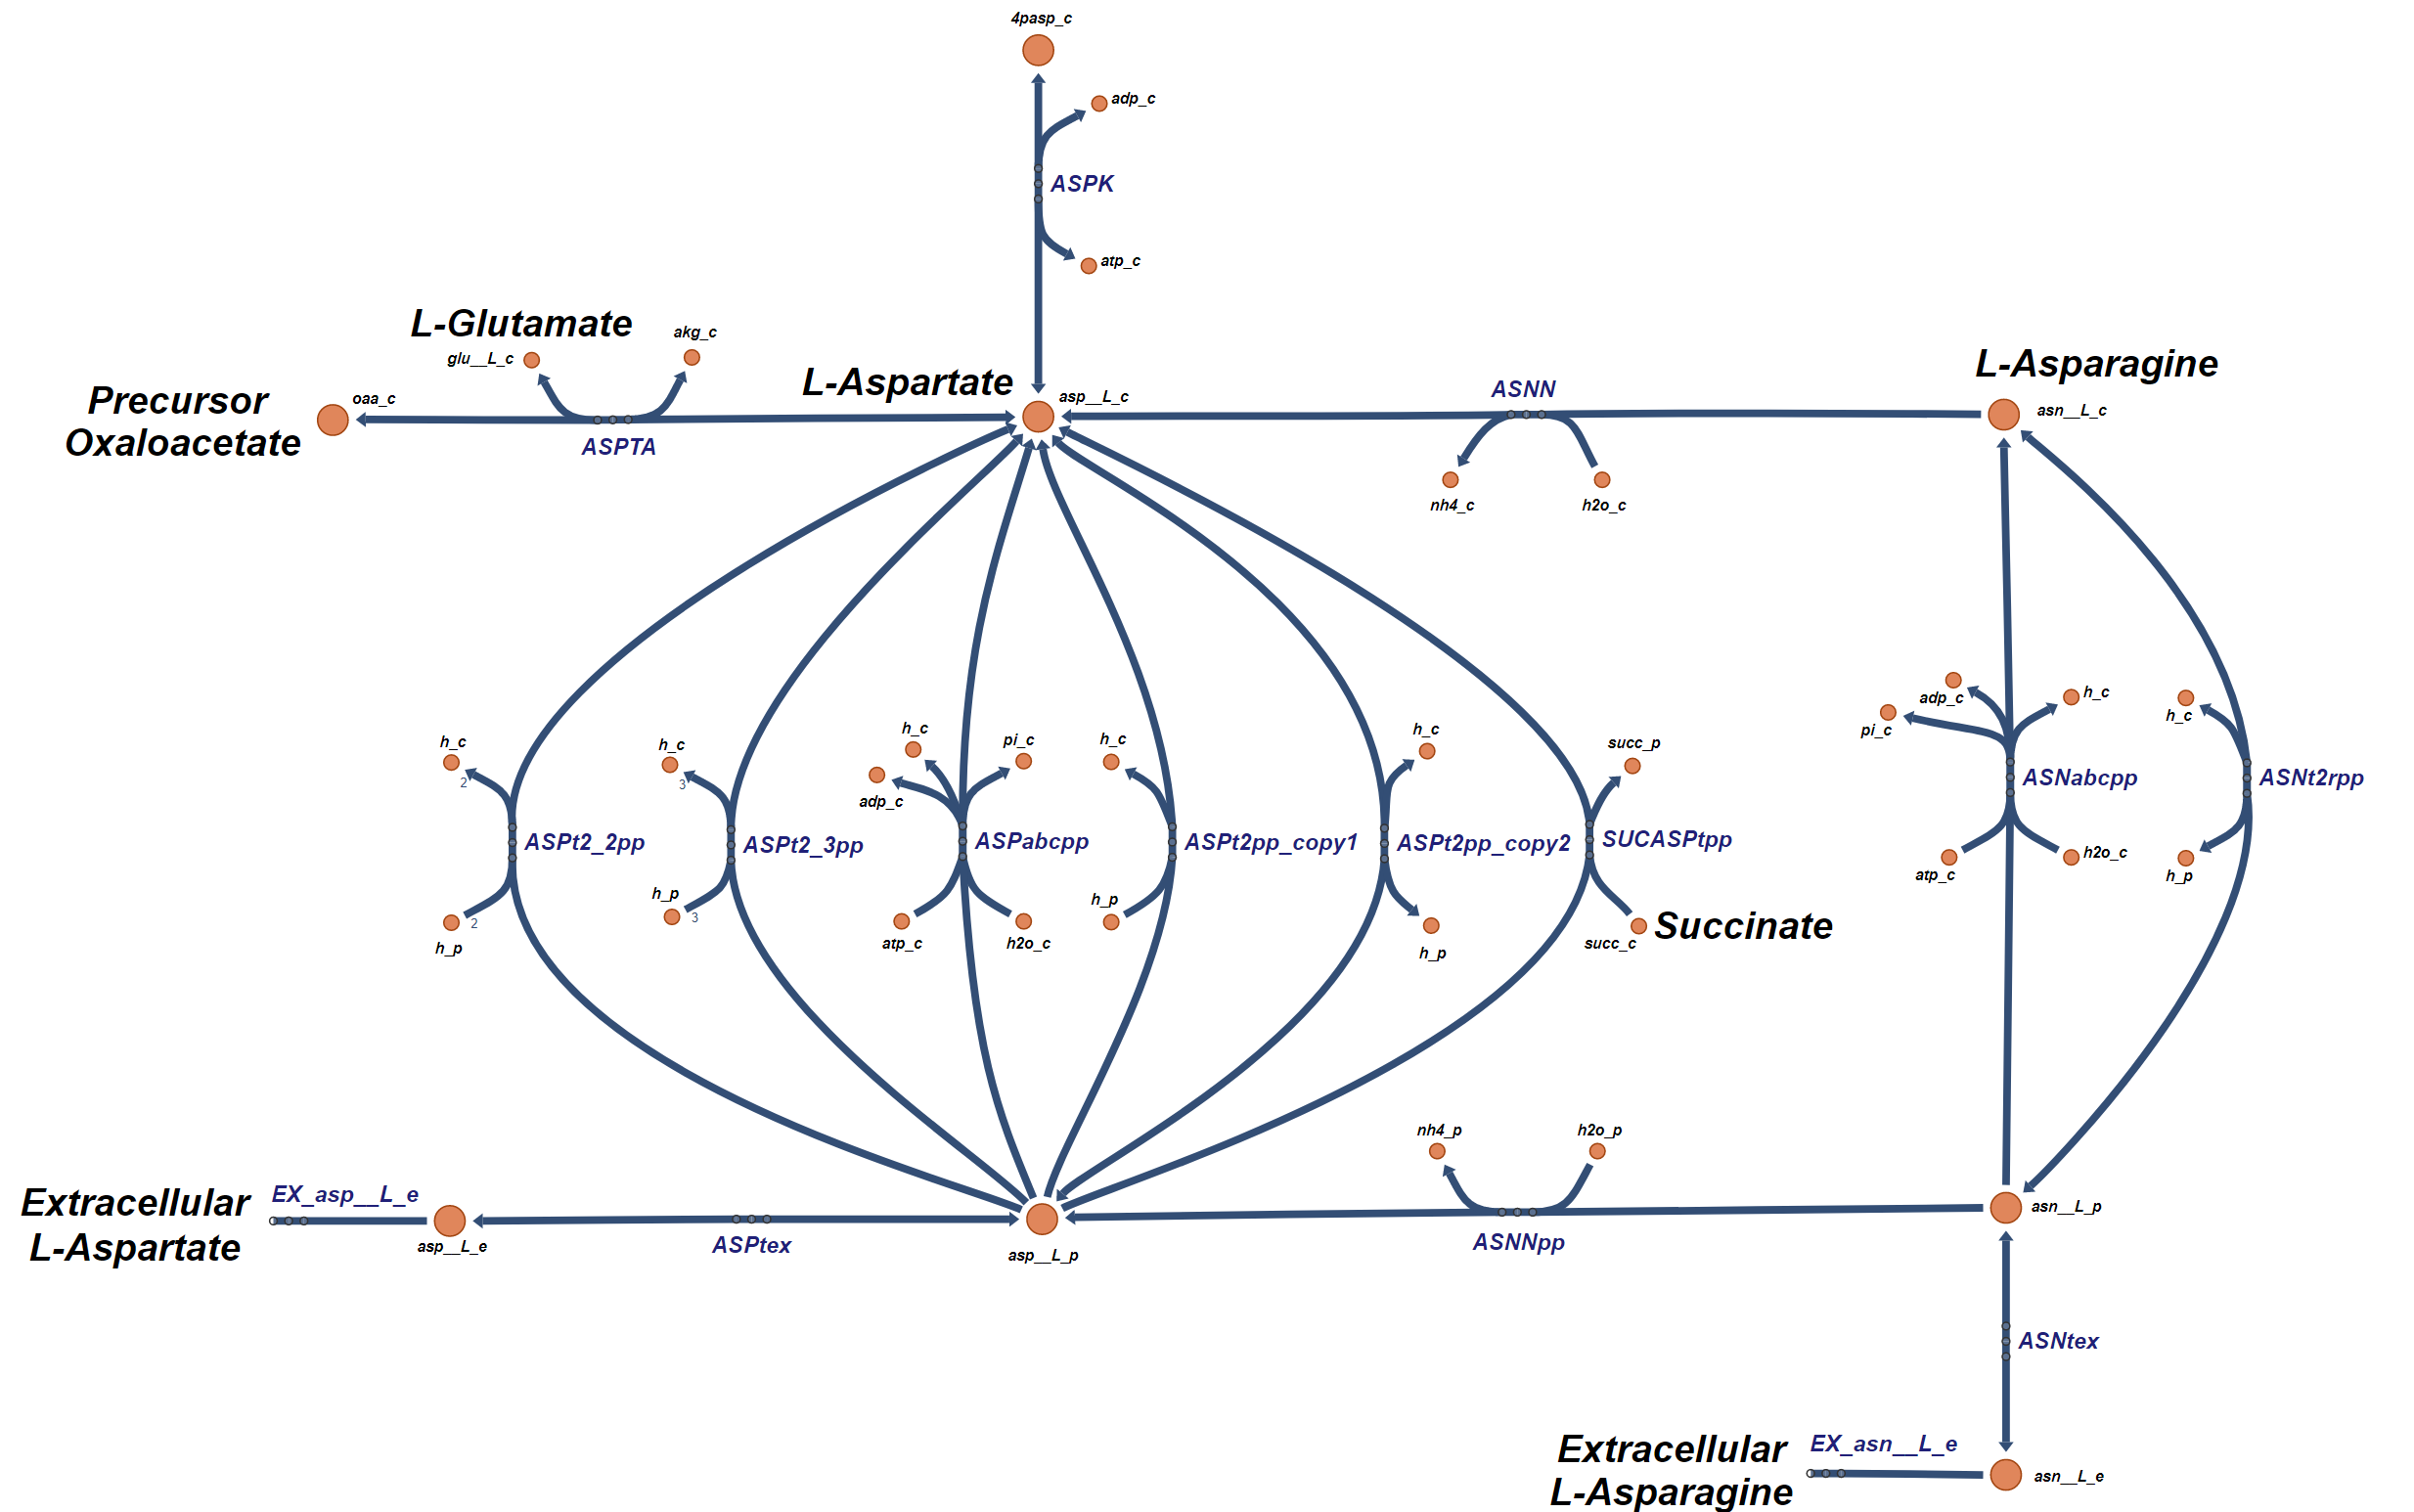

**Figure 6. **Biosynthesis pathways for the production of L-Leucine.

Now with this information we can define the reactions that create the pathways for the production of intercellular L-Leucine, they include 'ASPTA', 'ASNN', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and 'SUCASPtpp'. Now let's explore the potential pathways that lead to the production of L-Leucine. The primary pathway begins with the precursor oxaloacetate and passes through the 'ASPTA' reaction. A second collection of pathways begins with extracellular L-Leucine that diffuses into the periplasm ('EX_asp__L_e' and 'ASPtex') where it can be transported to the cytoplasm by one or more of the six available transporters ('ASPt2_2pp', 'ASPt2_3pp', 'ASPabcpp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and/or 'SUCASPtpp'). Another set of pathways that can produce L-asparate begins with extracellular L-Isoleucine where it can diffuse ('EX_asn__L_e' and 'ASNtex') into the cell's periplasm. At this point, the periplasmic L-Isoleucine can be converted into periplasmic L-Leucine through the reaction 'ASNNpp' where it can follow the previosuly described pathay to L-Leucine or it can be transported into the cytoplasm ('ASNabcpp' and/or 'ASNt2rpp') where it can be converted into L-Leucine through 'ASNN'. Finally, there is the reaction ('ASPK') which provides connectivity between the L-Leucine and the L-lysine & L-threonine metabolism.

LeucineReactions = transpose({'ASPTA','EX_asp__L_e','ASPtex','ASPabcpp','ASPt2_2pp','ASPt2_3pp','ASPt2pp_copy1','ASPt2pp_copy2','SUCASPtpp',...
    'EX_asn__L_e','ASNtex', 'ASNNpp','ASNabcpp','ASNt2rpp','ASNN','ASPK'});
[tmp,Leucine_rxnID] = ismember(LeucineReactions,model.rxns);
reactionNames = model.rxnNames(Leucine_rxnID);
reactionSubsystem = model.subSystems(Leucine_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',LeucineReactions)

T = 16×2 table
                                                reactionNames                                       reactionSubsystem         
                     ___________________________________________________________________    __________________________________

    ASPTA            'Aspartate transaminase'                                               'Alanine and Aspartate Metabolism'
    EX_asp__L_e      'L-Aspartate exchange'                                                 ''                                
    ASPtex           'L-aspartate transport via diffusion (extracellular to periplasm)'     'Transport, Outer Membrane Porin' 
    ASPabcpp         'L-aspartate transport via ABC system (periplasm)'                     'Transport, Inner Membrane'       
    ASPt2_2pp        'Aspartate transport via proton symport (2 H) (p

A table showing these reactions, the reaction name and the reaction formula is given below.

reactionFormulas = printRxnFormula(model,LeucineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',LeucineReactions)

T = 16×2 table
                                                reactionNames                                                     reactionFormulas                       
                     ___________________________________________________________________    _____________________________________________________________

    ASPTA            'Aspartate transaminase'                                               'akg_c + asp__L_c  <=> glu__L_c + oaa_c '                    
    EX_asp__L_e      'L-Aspartate exchange'                                                 'asp__L_e  -> '                                              
    ASPtex           'L-aspartate transport via diffusion (extracellular to periplasm)'     'asp__L_e  <=> asp__L_p '                                    
    ASPabcpp         'L-aspartate transport via ABC system (periplasm)'       

## 4.2. L-Leucine Aerobic Operation

Now let's explore the flux through these L-Leucine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(LeucineReactions, round(FBAsolution.x(Leucine_rxnID),3))

ASPTA	-2.876	
EX_asp__L_e	0	
ASPtex	0	
ASPabcpp	0	
ASPt2_2pp	0	
ASPt2_3pp	0	
ASPt2pp_copy1	0	
ASPt2pp_copy2	0	
SUCASPtpp	0	
EX_asn__L_e	0	
ASNtex	0	
ASNNpp	0	
ASNabcpp	0	
ASNt2rpp	0	
ASNN	0	
ASPK	1.05	


In this condition we can see that the only pathway for L-Leucine production is from the precursor 'oaa_c' using the 'ASPTA' reaction. There is a small amount of L-Leucine flux that is leaving the pool through 'ASPK'.

## 4.3 Excess L-Leucine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Leucine for the desired bioproduct.  What is the maximum amount of excess L-Leucine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'asp__L_c');

DM_asp__L_c	asp__L_c 	->	


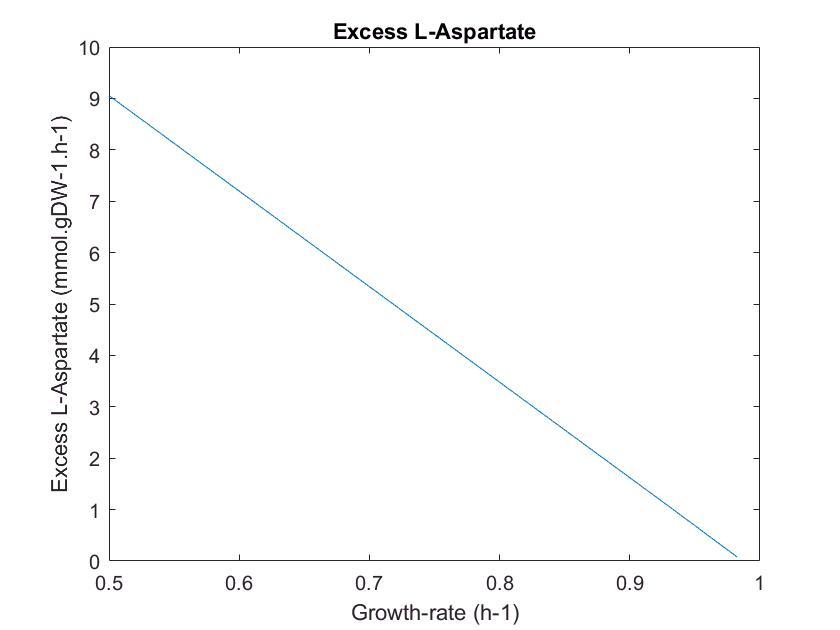

[tmp,Valine_MAX_rxnID] = ismember({'DM_asp__L_c'},model.rxns);
model = changeObjective(model,'DM_asp__L_c'); % Set the objective function
FBAsolution_Leucine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessLeucine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Leucine = optimizeCbModel(model,'max'); % Perform FBA
    excessLeucine(i) = FBAsolution_Leucine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessLeucine)
title('Excess L-Leucine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Leucine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Valine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Valine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Valine flux can increase from 0.07801 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 9.055 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Valine flux beyond these levels will require using the pathways that allow for the transport of L-Valine from the extracellular media. 

## **4. L-Isoleucine Biosynthesis**

L-Isoleucine is xxx

## 4.1.  **L-Isoleucine** Biosynthesis Pathways

According to the "Valine and Leucine Metabolism" subsystem (see Figure 1), which includes L_Isoleucine,  there is only two reactions that can produce cytoplasmic L-Isoleucine,  'ASNS1', 'ASNS2''. Both of these reaction convert  L-arpartate ('asp__L_c' ) to L-Isoleucine ('asn__L_c'). It is also important to note that both of these paths also require ATP. The pathway from the precursor oxaloacetate ('oaa_c') goes through the L-Aparartate pathway first.

To explore the posssibility of other L-Valine production pathways we can use the "sufNet" function to identify all the reactions that can produce L-Isoleucine.

surfNet(model, 'asn__L_c')


Met #298  asn__L_c, L-Asparagine, C4H8N2O3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are four reactions that can produce cytoplasmic L-Isoleucine in the forward direction, they include  'ASNS1', 'ASNS2', 'ASNabcpp', and 'ASNt2rpp'. The first two reactions were described above. The rest of the reactions are transporters that can be used to uptake L-Isoleucine ('asn__L_p')  from the periplasm to the cytoplasmic space ('asn__L_c').  The first of these transporters is an ABC transporter ( 'ASNabcpp') that requires ATP to move to transport the L-Isoleucine. The last reactions ( 'ASNt2rpp') require energy from the proton-motive force to transport L-Isoleucine. There are also no bidirectional "Consuming reactions' listed that can produce L-Isoleucine.

Now with this information we can define the reactions that create the pathways for the production of L-Leucine, they include  'ASNS1', 'ASNS2', 'ASNabcpp', and 'ASNt2rpp'.

IsoleucineReactions = transpose({'ASNS1','ASNS2','ASNabcpp','ASNt2rpp'});
[tmp,Isoleucine_rxnID] = ismember(IsoleucineReactions,model.rxns);
reactionNames = model.rxnNames(Isoleucine_rxnID);
reactionSubsystem = model.subSystems(Isoleucine_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',IsoleucineReactions)

T = 4×2 table
                                          reactionNames                                       reactionSubsystem         
                __________________________________________________________________    __________________________________

    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'Alanine and Aspartate Metabolism'
    ASNS2       'Asparagine synthetase'                                               'Alanine and Aspartate Metabolism'
    ASNabcpp    'L-asparagine transport via ABC system (periplasm)'                   'Transport, Inner Membrane'       
    ASNt2rpp    'L-asparagine reversible transport via proton symport (periplasm)'    'Transport, Inner Membrane'       


A table showing these reactions, the reaction name and the reaction formula is given below.

reactionFormulas = printRxnFormula(model,IsoleucineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',IsoleucineReactions)

T = 4×2 table
                                          reactionNames                                                                 reactionFormulas                                  
                __________________________________________________________________    ____________________________________________________________________________________

    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'asp__L_c + atp_c + gln__L_c + h2o_c  -> amp_c + asn__L_c + glu__L_c + h_c + ppi_c '
    ASNS2       'Asparagine synthetase'                                               'asp__L_c + atp_c + nh4_c  -> amp_c + asn__L_c + h_c + ppi_c '                      
    ASNabcpp    'L-asparagine transport via ABC system (periplasm)'                   'atp_c + h2o_c + asn__L_p  -> adp_c + asn__L_c + h_c + pi_c '                       
    

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Isoleucine.

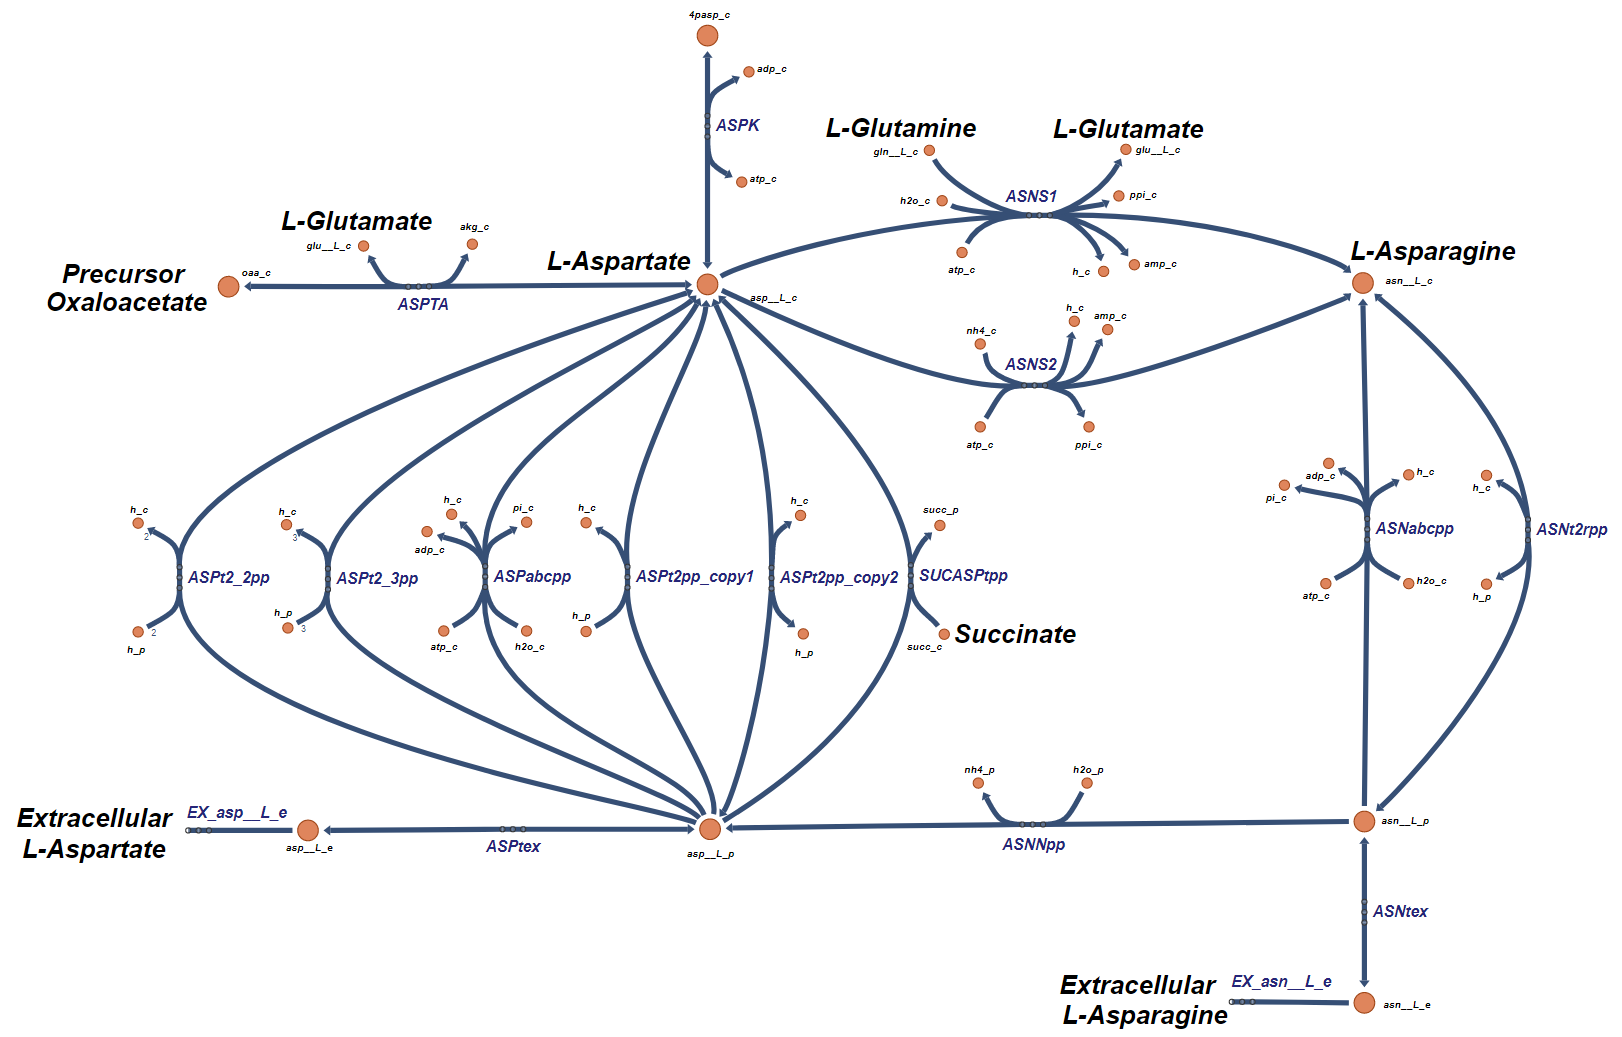

**Figure 3. **L-Isoleucine production pathways.

Now let's explore the potential pathways that lead to the production of L-Leucine. The primary pathway begins with the precursor oxaloacetate ('oaa_c') and passes through the 'ASPTA', 'ASNS1' and/or 'ASNS2' reactions. A second collection of pathways begins with extracellular L-Leucine that diffuses into the periplasm ('EX_asp__L_e' and 'ASPtex') where it can be transported to the cytoplasm by one or more of the six available transporters ('ASPt2_2pp', 'ASPt2_3pp', 'ASPabcpp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and/or 'SUCASPtpp') this flux can thier pass through 'ASNS1' and/or 'ASNS2' to add to the total L-Isoleucine flux. Another set of pathways that can produce L-Isoleucine begins with extracellular L-Isoleucine where it can diffuse ('EX_asn__L_e' and 'ASNtex') into the cell's periplasm. At this point, the periplasmic L-Isoleucine can be converted into periplasmic L-Leucine through the reaction 'ASNNpp' where it can follow the previosuly described pathay to L-Isoleucine or it can be transported into the cytoplasm ('ASNabcpp' and/or 'ASNt2rpp'). Finally, there is the pathway incolving 'ASPK' and 'ASNS1' and/or 'ASNS2' .

Now with this information we can define the reactions that create the pathways for the production of intercellular L-Isoleucine, they include 'ASPTA', 'ASNS1', 'ASNS2', 'EX_asp__L_e', 'ASPtex', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', 'SUCASPtpp', 'EX_asn__L_e' , 'ASNtex','ASNNpp', 'ASNabcpp', 'ASNt2rpp', and 'ASPK'.

Now let's explore the flux through these L-Isoleucine pathways under normal aerobic conditions.

model = saved_model;
IsoleucineReactions = transpose({'ASPTA','ASNS1','ASNS2','EX_asp__L_e','ASPtex','ASPabcpp','ASPt2_2pp',...
    'ASPt2_3pp','ASPt2pp_copy1','ASPt2pp_copy2','SUCASPtpp','EX_asn__L_e','ASNtex','ASNNpp','ASNabcpp',...
    'ASNt2rpp','ASPK'});
[tmp,Isoleucine_rxnID] = ismember(IsoleucineReactions,model.rxns);
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(IsoleucineReactions, round(FBAsolution.x(Isoleucine_rxnID),3))

ASPTA	-2.876	
ASNS1	0	
ASNS2	0.237	
EX_asp__L_e	0	
ASPtex	0	
ASPabcpp	0	
ASPt2_2pp	0	
ASPt2_3pp	0	
ASPt2pp_copy1	0	
ASPt2pp_copy2	0	
SUCASPtpp	0	
EX_asn__L_e	0	
ASNtex	0	
ASNNpp	0	
ASNabcpp	0	
ASNt2rpp	0	
ASPK	1.05	


In this condition we can see that the only pathway for L-Aspagine production is from the precursor 'oaa_c' using the 'ASNS2' and 'ASNS2'  reactions. There is also a small amount of L-Leucine flux that is leaving the pool through 'ASPK'.

## 4.3 Excess L-Isoleucine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Isoleucine for the desired bioproduct.  What is the maximum amount of excess L-Isoleucine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'asn__L_c');

DM_asn__L_c	asn__L_c 	->	


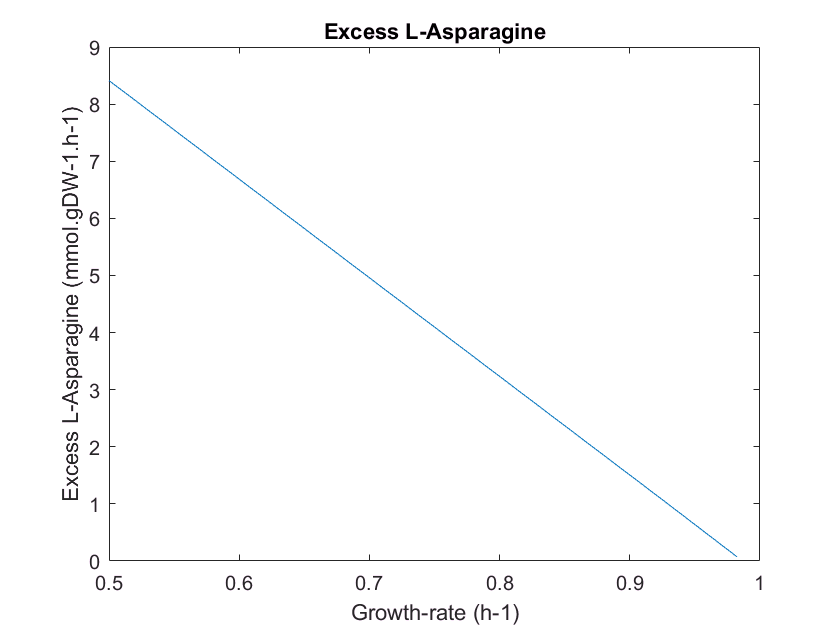

[tmp,Isoleucine_MAX_rxnID] = ismember({'DM_asn__L_c'},model.rxns);
model = changeObjective(model,'DM_asn__L_c'); % Set the objective function
FBAsolution_Isoleucine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessIsoleucine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Isoleucine = optimizeCbModel(model,'max'); % Perform FBA
    excessIsoleucine(i) = FBAsolution_Isoleucine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessIsoleucine)
title('Excess L-Isoleucine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Isoleucine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Isoleucine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Isoleucine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Isoleucine flux can increase from 0.07233 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 8.412 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Isoleucine flux beyond these levels will require using the pathways that allow for the transport of L-Isoleucine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

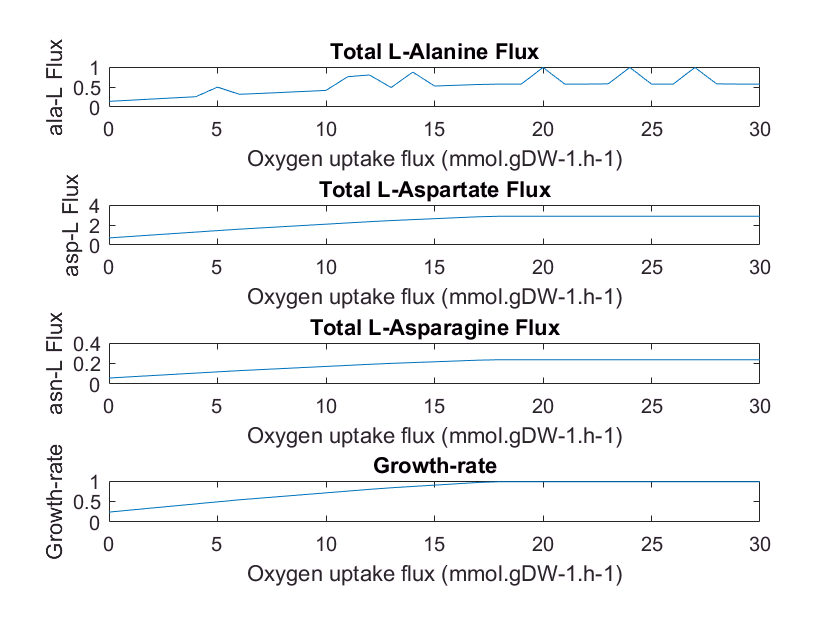

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
ala_flux = [];
asp_flux = [];
asn_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'ala__L_c'}, FBAsolution.x);
    ala_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'asp__L_c'}, FBAsolution.x);
    asp_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'asn__L_c'}, FBAsolution.x);
    asn_flux(k) = sum(vP);    
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(4,1,1); % top subplot
ax2 = subplot(4,1,2); % middle subplot
ax3 = subplot(4,1,3); % bottom subplot
ax4 = subplot(4,1,4); % bottom subplot

plot(ax1,oFlux,ala_flux)
title(ax1,'Total L-Valine Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'ala-L Flux');

plot(ax2,oFlux,asp_flux);
title(ax2,'Total L-Leucine Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'asp-L Flux'); 

plot(ax3,oFlux,asn_flux);
title(ax3,'Total L-Isoleucine Flux'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'asn-L Flux'); 

plot(ax4,oFlux,growthRate);
title(ax4,'Growth-rate'); 
xlabel(ax4,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax4,'Growth-rate'); 

**Figure 9.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

Note that the noise on the L-Valine chart is the result of loops in the production pathways. 

## 6. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Valine and Leucine Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-Valine, L-Leucine and L-Isoleucine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):